# Panel models

% cleaning
clear
close all
rehash path

addpath ../sandbox
addpath ../bear



## Prepare data and a reduced-form model


inputTbx = tablex.fromCsv("panel_data.csv");

estimStart = datex.q(1972,1);
estimEnd = datex.q(2014,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units=["US", "EA", "UK"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);

numSamples = 100;
rng(0);



## Cross-sectional static model


estimatorR5 = estimator.StaticCrossPanel(meta);
estimatorR5.Settings

ans =   StaticCrossPanel with properties:

            Alpha0: 1000
            Delta0: 1
            Burnin: 0
         Exogenous: [9×2 logical]
    BlockExogenous: 0
    Autoregression: [9×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [9×2 double]
           Lambda5: 1.0000e-03



modelR5 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR5 ...
    , stabilityThreshold=Inf ...
);

rng(0);
modelR5.initialize();
info5 = modelR5.presample(numSamples);

 Presampling model.ReducedForm (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



% disp('Beta Median Static Cross Panel Model:')
% betaMedian5 = calcMedian(modelR5,"beta")




## Cross-sectional Dynamic model

% This one is the most complicated and takes a lot of time to sample. Not going 
% to run it here now.

estimatorR6 = estimator.DynamicCrossPanel(meta);
estimatorR6.Settings

ans =   DynamicCrossPanel with properties:

            Alpha0: 1000
            Delta0: 1
                A0: 1000
                B0: 1
               Rho: 0.7500
               Psi: 0.1000
             Gamma: 0.8500
            Burnin: 0
         Exogenous: [9×2 logical]
    BlockExogenous: 0
    Autoregression: [9×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [9×2 double]
           Lambda5: 1.0000e-03



modelR6 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR6 ...
    , stabilityThreshold=Inf ...
);

rng(0);
modelR6.initialize();
info6 = modelR6.presample(10);

 Presampling model.ReducedForm (DynamicCrossPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



## Indentify a SVAR using Cholesky (without reordering)


identChol = identifier.Cholesky(order=[]);

modelS5 = model.Structural(reducedForm=modelR5, identifier=identChol);
modelS5.initialize();
info5 = modelS5.presample(numSamples);

 Presampling model.Structural (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




modelS5.Presampled{1}

ans = struct with fields:
                  beta: [342×1 double]
                 sigma: [81×1 double]
    IdentificationDraw: [1×1 struct]
                     D: [9×9 double]


modelS5.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [9×9 double]


modelS5.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.1931    0.1527    0.1527    0.1411    0.1007    0.1007    0.1411    0.1007    0.1007
    0.1527    0.1873    0.1527    0.1007    0.1353    0.1007    0.1007    0.1353    0.1007
    0.1527    0.1527    0.2170    0.1007    0.1007    0.1651    0.1007    0.1007    0.1651
    0.1411    0.1007    0.1007    0.1938    0.1533    0.1533    0.1411    0.1007    0.1007
    0.1007    0.1353    0.1007    0.1533    0.1880    0.1533    0.1007    0.1353    0.1007
    0.1007    0.1007    0.1651    0.1533    0.1533    0.2177    0.1007    0.1007    0.1651
    0.1411    0.1007    0.1007    0.1411    0.1007    0.1007    0.1989    0.1584    0.1584
    0.1007    0.1353    0.1007    0.1007    0.1353    0.1007    0.1584    0.1930    0.1584
    0.1007    0.1007    0.1651    0.1007    0.1007    0.1651    0.1584    0.1584    0.2228
    0.0145   -0.0260   -0.0260   -0.0375   -0.0779   -0.0779   -0.0375   -0.0779   -0.0779


modelS5.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.1931    0.1527    0.1527    0.1411    0.1007    0.1007    0.1411    0.1007    0.1007
    0.1527    0.1873    0.1527    0.1007    0.1353    0.1007    0.1007    0.1353    0.1007
    0.1527    0.1527    0.2170    0.1007    0.1007    0.1651    0.1007    0.1007    0.1651
    0.1411    0.1007    0.1007    0.1938    0.1533    0.1533    0.1411    0.1007    0.1007
    0.1007    0.1353    0.1007    0.1533    0.1880    0.1533    0.1007    0.1353    0.1007
    0.1007    0.1007    0.1651    0.1533    0.1533    0.2177    0.1007    0.1007    0.1651
    0.1411    0.1007    0.1007    0.1411    0.1007    0.1007    0.1989    0.1584    0.1584
    0.1007    0.1353    0.1007    0.1007    0.1353    0.1007    0.1584    0.1930    0.1584
    0.1007    0.1007    0.1651    0.1007    0.1007    0.1651    0.1584    0.1584    0.2228
    0.0145   -0.0260   -0.0260   -0.0375   -0.0779   -0.0779   -0.0375   -0.0779   -0.0779




modelS6 = model.Structural(reducedForm=modelR6, identifier=identChol);
modelS6.initialize();
info6 = modelS6.presample(10);

 Presampling model.Structural (DynamicCrossPanel) [10]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



## Impulse responses

% Static model

prctileFunc = @(x) prctile(x, [10, 50, 90], 2);
resp5 = modelS5.simulateResponses();
respPct5 = tablex.apply(resp5, prctileFunc);
respPct5 = tablex.flatten(respPct5);

resp5

resp5 = 24×9 timetable
     Time          US_YER           US_HICSA           US_STN            EA_YER           EA_HICSA           EA_STN            UK_YER           UK_HICSA           UK_STN    
    _______    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________

    2014-Q1    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 double
    2014-Q2    1×100×9 double    1×100×9 double    1×100×9 double    1×100×9 dou

respPct5

respPct5 = 24×81 timetable
     Time                US_YER___US_DEM                         US_YER___US_SUP                        US_YER___US_POL                        US_YER___EA_DEM                           US_YER___EA_SUP                        US_YER___EA_POL                       US_YER___UK_DEM                        US_YER___UK_SUP                      US_YER___UK_POL                       US_HICSA___US_DEM                      US_HICSA___US_SUP                   US_HICSA___US_POL                      US_HICSA___EA_DEM                         US_HICSA___EA_SUP                        US_HICSA___EA_POL                       US_HICSA___UK_DEM                        US_HICSA___UK_SUP

## Plot results

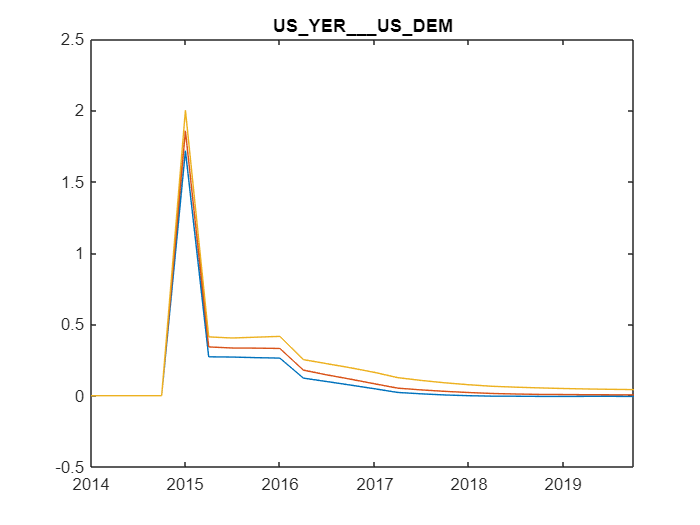


close all

figure();
tablex.plot(respPct5, "US_YER___US_DEM");
title("US_YER___US_DEM", interpreter="none");

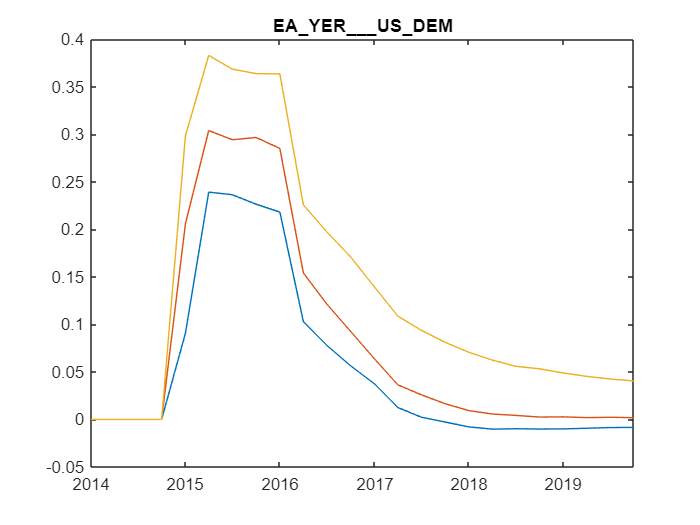


figure();
tablex.plot(respPct5, "EA_YER___US_DEM");
title("EA_YER___US_DEM", interpreter="none");

## Uncoditional forecast

fcastStart = datex.shift(modelS5.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS5.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);


Static model

fcastTbx5 = modelS5.forecast(fcastSpan);
fcastPrctileTbx5 = tablex.apply(fcastTbx5, prctileFunc);
fcastPrctileTbx5 = tablex.flatten(fcastPrctileTbx5);

fcastTbx5

fcastTbx5 = 15×18 timetable
     Time         US_YER         US_HICSA         US_STN          EA_YER         EA_HICSA         EA_STN          UK_YER         UK_HICSA         UK_STN       resid_US_YER    resid_US_HICSA    resid_US_STN    resid_EA_YER    resid_EA_HICSA    resid_EA_STN    resid_UK_YER    resid_UK_HICSA    resid_UK_STN
    _______    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ______

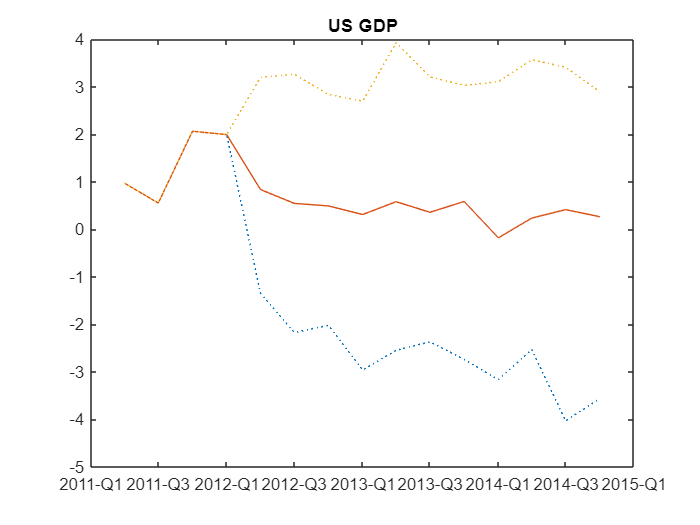


tablex.plot( ...
    fcastPrctileTbx5, "US_YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);
title("US GDP");

## Create forecast assumptions


fcastStart = datex.shift(estimEnd, 1);
fcastEnd = datex.shift(estimEnd, 12);
fcastSpan = datex.span(fcastStart, fcastEnd);
initStart = datex.shift(fcastStart, -modelS5.Meta.Order);

[dataTbx, planTbx] = tablex.forConditional(modelS5, fcastSpan);

dataTbx{datex("2015-Q4"), "US_YER"} = -1.5;
dataTbx{datex("2016-Q4"), "UK_HICSA"} = 5.5;

dataTbx{:, "Oil"} = inputTbx{end, "Oil"};

dataTbx

dataTbx = 12×10 timetable
     Time      US_YER    US_HICSA    US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN     Oil 
    _______    ______    ________    ______    ______    ________    ______    ______    ________    ______    _____

    2015-Q1      NaN       NaN        NaN       NaN        NaN        NaN       NaN        NaN        NaN      94.32
    2015-Q2      NaN       NaN        NaN       NaN        NaN        NaN       NaN        NaN        NaN      94.32
    2015-Q3      NaN       NaN        NaN       NaN        NaN        NaN       

planTbx

planTbx = 12×9 timetable
     Time      US_YER    US_HICSA    US_STN    EA_YER    EA_HICSA    EA_STN    UK_YER    UK_HICSA    UK_STN
    _______    ______    ________    ______    ______    ________    ______    ______    ________    ______

    2015-Q1      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q2      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q3      ""         ""         ""        ""         ""         ""        ""         ""         ""  
    2015-Q4      ""       

## Run conditional forecast


rng(0);
cfcastTbx5 = modelS5.conditionalForecast(fcastSpan, conditions=dataTbx, plan=[]);

 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



cfcastPrctilesTbx5 = tablex.apply(cfcastTbx5, prctileFunc);



## Plot results of conditional forecast

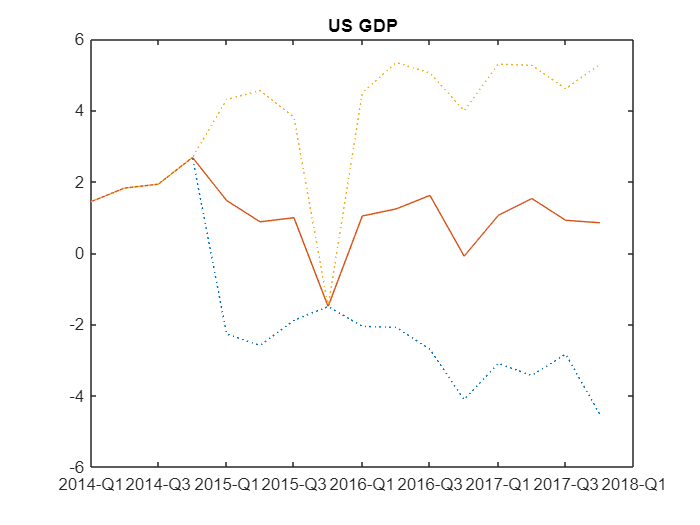

tablex.plot( ...
    cfcastPrctilesTbx5, "US_YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);
title("US GDP");